h5disp('forceFieldVariableLangevin/test/trajectory0/blocks_0-99.h5');

HDF5 blocks_0-99.h5 
Group '/' 
    Group '/0' 
        Attributes:
            'potentialEnergy':  5.990109
            'kineticEnergy':  1.426166
            'time':  12.222280
            'block':  0
        Dataset 'pos' 
            Size:  3x100
            MaxSize:  3x100
            Datatype:   H5T_IEEE_F32LE (single)
            ChunkSize:  3x100
            Filters:  deflate(9)
    Group '/1' 
        Attributes:
            'potentialEnergy':  6.162194
            'kineticEnergy':  1.358231
            'time':  21.417556
            'block':  1
        Dataset 'pos' 
            Size:  3x100
            MaxSize:  3x100
            Datatype:   H5T_IEEE_F32LE (single)
            ChunkSize:  3x100
            Filters:  deflate(9)
    Group '/10' 
        Attributes:
            'potentialEnergy':  5.552755
            'kineticEnergy':  1.648419
            'time':  97.080577
            'block':  10
        Dataset 'pos' 
            Size:  3x100
            MaxSize:  3x100
   

get pos-data

pos_list=zeros(3,400,100);
for i=1:10
    F=['initial_stateRandomWalk/trajectory',num2str(i-1),'/blocks_0-0.h5'];
    pos = h5read(F,'////0/pos');
    for m=1:3
        for n=1:400
            pos_list(m,n,i)=pos(m,n);
        end
    end
end

Plotting

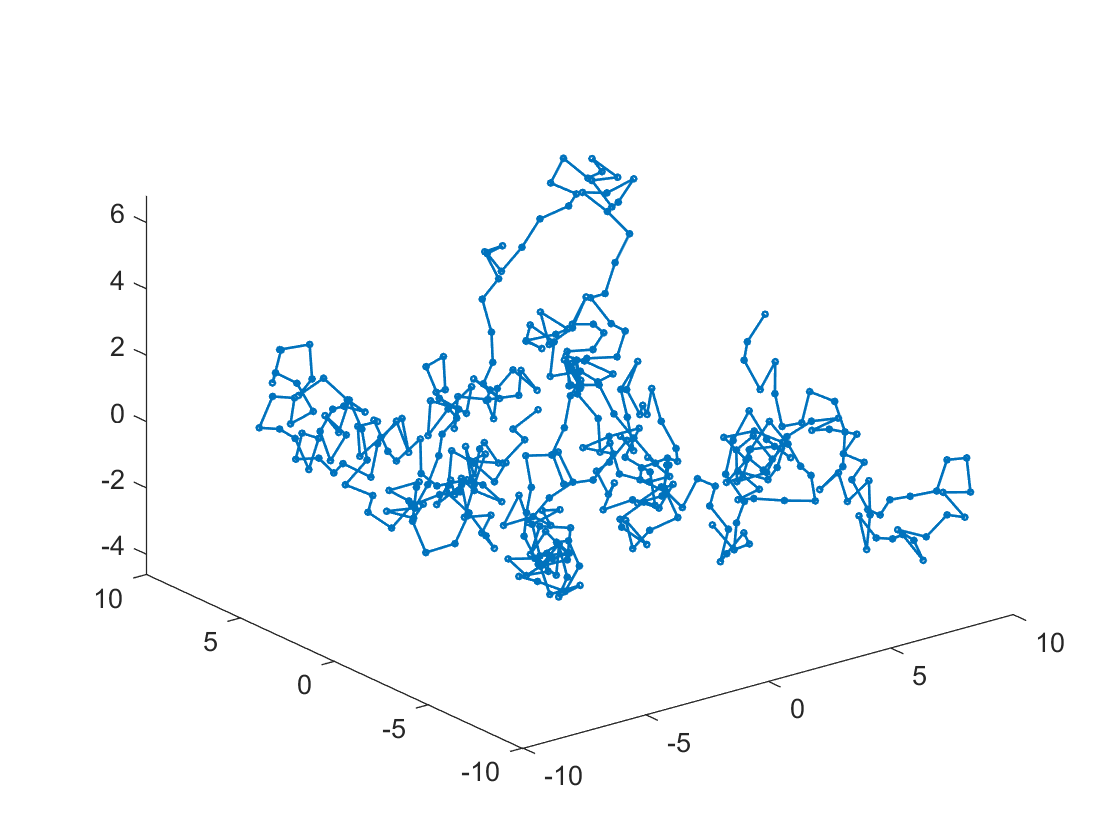

figure
i=1;
plot3(pos_list(1,:,i),pos_list(2,:,i),pos_list(3,:,i),'-o','MarkerSize',2,"LineWidth",1);